clear 
close all
clc


% To fill in right parameters and convert data files to surface height

date = '09';
ampl_value = 7;
rot_rate = 0.4189;
rot_rate = string(rot_rate);
freq_value = 2.4;
freq_value = string(freq_value);
% Define the base directory for input and output files
input_dir = sprintf('D:\\Matlab\\Matlab input\\202409%s_full_plate_final\\202409%s_%sradps_%sHz_%smm_full_plate_separate_frames\\Results\\', date, date,rot_rate,freq_value,string(ampl_value));
output_dir = sprintf('D:\\Matlab\\Matlab output\\202409%s_full_plate_final_results\\202409%s_%sradps_%sHz_%smm_full_plate\\FFT\\', date, date,rot_rate,freq_value,string(ampl_value));

% input_dir = 'D:\Matlab\Matlab input\20240715_full_plate\20240715_rot_2.6Hz_9mm_full_plate_separate_frames\Results\';
% output_dir = 'D:\Matlab\Matlab output\20240715_full_plate_results\20240715_rot_2.6Hz_9mm_full_plate\FFT\';


% Define the base file name and extension
base_file_name = sprintf('202409%s_%sradps_%sHz_%smm_full_plate_frame_', date,rot_rate,freq_value,string(ampl_value));

% base_file_name = '20240715_rot_2.6Hz_9mm_full_plate_frame_';


file_extension = 'A_vel_new.dat';

frame_num = 300;
% Construct the file name
frame_str = sprintf('%04d', frame_num);
file_name = [base_file_name, frame_str, file_extension];
input_file = fullfile(input_dir, file_name);

% Load the data
dr = loadvec(input_file);

% Copy dr to dr_new & delete rows and columns with only zeros
dr_new = dr;
dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
dr_new.vy(all(dr_new.vy == 0, 2), :) = [];

% Compute the surface height
h_0 = 150; % surface-pattern distance in mm
h = surfheight(dr_new, h_0);
surface_height = h.w;


% Plot the amplitude/surface height over the long axis
%ampl = surface_height(30,:,2);
surf_height_long_axis = surface_height(:,30);
ampl_long_axis = surf_height_long_axis - mean(surf_height_long_axis); % is in mm
%ampl = surface_height(30,40,:);
values_long_axis = (h.x / 10) + 5.664; % in cm
%values_time_axis = start_frame:1:end_frame;
plot(values_long_axis,surf_height_long_axis)
%plot(values_time_axis,ampl)
title('Surface height over long axis')
xlabel('x (cm)')
ylabel('Surface height (mm)')
% output_file_png_surf_height_long = fullfile(output_dir, sprintf('202409%s_%sradps_%sHz_%smm_full_plate_surf_height_long_axis_%s.png', date,rot_rate,freq_value,string(ampl_value), string(frame_num)));
% exportgraphics(gcf, output_file_png_surf_height_long);
% output_file_fig_surf_height_long = fullfile(output_dir, sprintf('202409%s_%sradps_%sHz_%smm_full_plate_surf_height_long_axis_%s.fig', date,rot_rate,freq_value,string(ampl_value), string(frame_num)));
% savefig(gcf, output_file_fig_surf_height_long);

L_long_axis = length(surf_height_long_axis);

plot(values_long_axis,ampl_long_axis)
title('Amplitude over long axis')
xlabel('x (cm)')
ylabel('Amplitude (mm)')

% output_file_png_ampl_long = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_ampl_long_axis_%s.png',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% exportgraphics(gcf, output_file_png_ampl_long);
% output_file_fig_ampl_long = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_ampl_long_axis_%s.fig',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% savefig(gcf, output_file_fig_ampl_long);


% % Example function
% %Ts = 1/50;
% distance = 0.0005;
% x = 0:distance:5-distance;
% k = 20;
% water_surface = sin(k*x); % + sin(2*pi*2*k*x);
% plot(x,water_surface)
% xlabel('x (m)')
% ylabel('Amplitude')
% 
% % Code with known example filled in
% 
% %Fourier over long axis
% four_1d_long_axis = fft(water_surface); %fft(ampl_long_axis/1000);
% % Distance between points in meters
% %distance = (h.x(2) - h.x(1)) / 1000;
% 
% L_try_out = length(x);
% 
% %OPTION 1
% wave_num_long_axis = 2*pi/distance; %1/distance;
% wave_num_four_long_axis = (0:length(four_1d_long_axis)-1)*wave_num_long_axis/length(four_1d_long_axis); %(0:length(four_1d_long_axis)-1)*wave_num_long_axis/length(four_1d_long_axis);
% 
% % Plot the Fourier transform against frequencies
% plot(wave_num_four_long_axis,2*abs(four_1d_long_axis/L_try_out)) %plot(wave_num_four_long_axis,2*abs(four_1d_long_axis/L_long_axis))
% xlabel('Wave number')
% ylabel('Magnitude')
% title(sprintf('FFT over long axis %s %sHz %smm',rot_rate,freq_value,string(ampl_value)))
% %xlim([0 50]);
% % ylim([0 8]);
% 
% % n = length(x);
% % fshift = (-n/2:n/2-1)*(wave_num_long_axis/n);
% % yshift = fftshift(four_1d_long_axis);
% % plot(fshift,abs(yshift))
% % xlabel('Frequency (Hz)')
% % ylabel('Magnitude')


%Fourier over long axis
four_1d_long_axis = fft(ampl_long_axis/1000);
% Distance between points in meters
distance = (h.x(2) - h.x(1)) / 1000; 


%OPTION 1
wave_num_long_axis = 2*pi/distance;
wave_num_four_long_axis = (0:length(four_1d_long_axis)-1)*wave_num_long_axis/length(four_1d_long_axis);

% Plot the Fourier transform against frequencies
plot(wave_num_four_long_axis,2*abs(four_1d_long_axis/L_long_axis))
xlabel('Wave number')
ylabel('Magnitude')
title(sprintf('FFT long axis %s %sHz %smm',rot_rate,freq_value,string(ampl_value)))
xlim([0 150]);

% To calculate integral under peak

% Define the range for wave numbers where the peak is located
a = 10.917405663017071;  % Start of the wave number range for the peak (example)
b = 21.834811326034142;  % End of the wave number range for the peak (example)

% Isolate the data points within this range
idx = (wave_num_four_long_axis >= a) & (wave_num_four_long_axis <= b);
wave_num_peak = wave_num_four_long_axis(idx);
magnitude_peak = 2 * abs(four_1d_long_axis(idx) / L_long_axis);

% Perform numerical integration using trapezoidal method
area_under_peak = trapz(wave_num_peak, magnitude_peak);

% Display the result
fprintf('The integral under the peak is: %.4f\n', area_under_peak);


% ylim([0 8]);

% n = length(ampl_long_axis);
% fshift = (-n/2:n/2-1)*(wave_num_long_axis/n);
% yshift = fftshift(four_1d_long_axis);
% plot(fshift,abs(yshift))
% xlabel('Frequency (Hz)')
% ylabel('Magnitude')
% xlim([0 30]);


% Surface height on short axis
% Plot the amplitude/surface height over the short axis
surf_height_short_axis = surface_height(170,:);
ampl_short_axis = surf_height_short_axis - mean(surf_height_short_axis);
values_short_axis = h.y/10; % in cm
plot(values_short_axis,surf_height_short_axis)
title('Surface height over short axis')
xlabel('Position on short axis (cm)')
ylabel('Surface height (mm)')

% output_file_png_surf_height_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_surf_height_short_axis_%s.png',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% exportgraphics(gcf, output_file_png_surf_height_short);
% output_file_fig_surf_height_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_surf_height_short_axis_%s.fig',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% savefig(gcf, output_file_fig_surf_height_short);

% Fit a polynomial (e.g., a linear fit) to the surface height data
p_short_axis = polyfit(values_short_axis, surf_height_short_axis, 1);  % 1 for linear fit

% Calculate the fitted values
fitted_values_short_axis = polyval(p_short_axis, values_short_axis);

% Subtract the fitted values from the original data to obtain the fluctuations
fluctuations_short_axis = surf_height_short_axis - fitted_values_short_axis;

% Plot the fluctuations
figure;
plot(values_short_axis, fluctuations_short_axis);
title('Surface height fluctuations over short axis');
xlabel('Position on short axis (cm)');
ylabel('Surface height fluctuations (mm)');
% output_file_png_fluc_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_fluc_short_axis_%s.png',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% exportgraphics(gcf, output_file_png_fluc_short);
% output_file_fig_fluc_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_fluc_short_axis_%s.fig',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% savefig(gcf, output_file_fig_fluc_short);

% 
% % plot(values_short_axis,ampl_short_axis)
% % title('Amplitude over short axis')
% % xlabel('Position on short axis')
% % ylabel('Amplitude')
% 
% 
% L_short_axis = length(fluctuations_short_axis/1000);
% 
% % Compute Fourier transform and rewrite frequency
% 
% %Fourier over short axis
% four_1d_short_axis = fft(fluctuations_short_axis);
% distance_short_axis = (h.y(2)-h.y(1))/1000; % Distance between two values
% freq_short_axis = 1/distance_short_axis; % per meter
% freq_four_short_axis = (0:length(four_1d_short_axis)-1)*freq_short_axis/length(four_1d_short_axis);
% 
% % Plot the Fourier transform against frequencies
% plot(freq_four_short_axis,2*abs(four_1d_short_axis/L_short_axis))
% xlabel('Wave number')
% ylabel('Magnitude')
% title(sprintf('FFT over short axis %s 2.6Hz %smm',rot_rate,string(ampl_value)))
% xlim([0 60]);
% %ylim([0 0.1]);
% output_file_png_fft_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_FFT_short_axis_%s.png',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% exportgraphics(gcf, output_file_png_fft_short);
% output_file_fig_fft_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_FFT_short_axis_%s.fig',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% savefig(gcf, output_file_fig_fft_short);

%Fourier over short axis
four_1d_short_axis = fft(fluctuations_short_axis/1000);
% Distance between points in meters
distance_short = (h.y(2) - h.y(1)) / 1000; 
L_short_axis = length(fluctuations_short_axis/1000);

%OPTION 1
wave_num_short_axis = 2*pi/distance_short;
wave_num_four_short_axis = (0:length(four_1d_short_axis)-1)*wave_num_short_axis/length(four_1d_short_axis);

% Plot the Fourier transform against frequencies
plot(wave_num_four_short_axis,2*abs(four_1d_short_axis/L_short_axis))
xlabel('Wave number')
ylabel('Magnitude')
title(sprintf('FFT short axis %s %sHz %smm',rot_rate,freq_value,string(ampl_value)))
xlim([0 150]);
% ylim([0 8]);

% n = length(ampl_long_axis);
% fshift = (-n/2:n/2-1)*(wave_num_long_axis/n);
% yshift = fftshift(four_1d_long_axis);
% plot(fshift,abs(yshift))
% xlabel('Frequency (Hz)')
% ylabel('Magnitude')
% xlim([0 30]);


clear 
close all
clc

date = '09';
rot_rate = 0.4189;
rot_rate = string(rot_rate);
freq_value = 2.4;
freq_value = string(freq_value);
ampl_value = 7;
ampl_value = string(ampl_value);

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Load the surface height data
surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate.mat', rot_rate, freq_value, ampl_value)];
data = load(surface_height_file);
surface_height_3D = data.surface_height_3D; % 3D matrix (x, y, time)

% Load the x and y coordinate arrays
x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

x_data = load(x_positions_file);
y_data = load(y_positions_file);

x_positions = x_data.x_positions_array; % Array of x positions
y_positions = y_data.y_positions_array; % Array of y positions


surf_height_y_axis = surface_height_3D(170,:,131);

plot(y_positions,surf_height_y_axis)
title('Surface height over short axis')
xlabel('x (cm)')
ylabel('Surface height (mm)')

% Fit a polynomial (e.g., a linear fit) to the surface height data
p_y_axis = polyfit(y_positions, surf_height_y_axis, 1);  % 1 for linear fit

% Calculate the fitted values
fitted_values_y_axis = polyval(p_y_axis, y_positions);

% Subtract the fitted values from the original data to obtain the fluctuations
fluctuations_y_axis = surf_height_y_axis - fitted_values_y_axis;

% Plot the fluctuations
figure;
plot(y_positions, fluctuations_y_axis);
title('Surface height fluctuations over short axis');
xlabel('x (cm)');
ylabel('Surface height fluctuations (mm)');

%Fourier over y axis
four_1d_y_axis = fft(fluctuations_y_axis/100);
% Distance between points in meters
distance_y = (y_positions(2) - y_positions(1)) / 100
L_y_axis = length(fluctuations_y_axis/100)


wave_num_y_axis = 2*pi/distance_y;
wave_num_four_y_axis = (0:length(four_1d_y_axis)-1)*wave_num_y_axis/length(four_1d_y_axis);

% Plot the Fourier transform against frequencies
plot(wave_num_four_y_axis,2*abs(four_1d_y_axis/L_y_axis))
xlabel('Wave number')
ylabel('Amplitude (m)')
title(sprintf('FFT y axis %s %sHz %smm',rot_rate,freq_value,string(ampl_value)))
%xlim([0 500]);
% ylim([0 8]);

% Save the figure in different formats
% Directory for saving figures
figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\';
file_name = [figures_directory, sprintf('FFT_y_axis_%sradps_%sHz_%smm', rot_rate, freq_value, ampl_value)]; % Combine directory and file name

% Save as a MATLAB figure (.fig)
saveas(gcf, [file_name, '.fig']); % Save the figure as .fig file

% Save as PNG file
saveas(gcf, [file_name, '.png']); % Save the figure as .png file

clear 
close all
clc

% Parameters
date = '09';
%rotation_rates = [0, 0.0524, 0.1047, 0.2094, 0.4189, 0.8378];
rotation_rates = [0, 0.0524, 0.2094, 0.4189, 0.8378];
%rotation_rates_labels = [0, 0.0083, 0.0167, 0.0333, 0.0667, 0.1333];
rotation_rates_labels = [0, 0.0083, 0.0333, 0.0667, 0.1333];
freq_value = 2.5;  % Only one frequency as per your example
freq_value_str = string(freq_value);
amplitudes = [3, 5, 7, 9];

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Load the x and y coordinate arrays
x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

x_data = load(x_positions_file);
y_data = load(y_positions_file);

x_positions = x_data.x_positions_array; % Array of x positions
y_positions = y_data.y_positions_array; % Array of y positions
num_x_positions = length(x_positions);
L_y_axis = length(y_positions);

% Distance between points in meters (for wave number calculation)
distance_y = (y_positions(2) - y_positions(1)) / 100;
wave_num_y_axis = 2 * pi / distance_y;
wave_num_four_y_axis = (0:L_y_axis-1) * wave_num_y_axis / L_y_axis;

% Initialize a table to store results
results_table = table('Size', [0 8], ...
                      'VariableTypes', {'double', 'double', 'double', 'double', 'double', 'double', 'double', 'double'}, ...
                      'VariableNames', {'RotationRate', 'Amplitude', 'Peak1_WaveNumber', 'Peak1_Amplitude_mm', ...
                                       'Peak2_WaveNumber', 'Peak2_Amplitude_mm', 'Peak3_WaveNumber', 'Peak3_Amplitude_mm'});

% Loop through each rotation rate
for rot_idx = 1:length(rotation_rates)
    rot_rate = rotation_rates(rot_idx);
    rot_rate_label = rotation_rates_labels(rot_idx);
    
    % Create a new figure for the current rotation rate
    figure('Position', [100, 100, 1200, 500]); % Adjust figure size for better visibility
    
    % Create an invisible uicontrol for extra padding above the sgtitle
    uicontrol('Style', 'text', 'Position', [0, 460, 1200, 40], 'Visible', 'off');

    % Loop through each amplitude combination
    for ampl_idx = 1:length(amplitudes)
        ampl_value = amplitudes(ampl_idx);
        
        % Load the surface height data for the current experiment
        rot_rate_str = string(rot_rate);
        ampl_value_str = string(ampl_value);
        surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate.mat', rot_rate_str, freq_value_str, ampl_value_str)];
        
        % Check if the file exists to avoid errors
        if ~isfile(surface_height_file)
            warning('File %s not found. Skipping.', surface_height_file);
            continue;
        end
        
        % Load data
        data = load(surface_height_file);
        surface_height_3D = data.surface_height_3D; % 3D matrix (x, y, time)

        % Preallocate for accumulating Fourier transforms
        accumulated_fourier = zeros(1, L_y_axis);

        % Loop through each x-position
        for i = 1:num_x_positions
            % Select surface height data at current x position and specific timestamp (e.g., timestamp 80)
            surf_height_y_axis = surface_height_3D(i, :, 80);

            % Fit a polynomial (e.g., a linear fit) to the surface height data
            p_y_axis = polyfit(y_positions, surf_height_y_axis, 1);  % 1 for linear fit

            % Calculate the fitted values and get fluctuations
            fitted_values_y_axis = polyval(p_y_axis, y_positions);
            fluctuations_y_axis = surf_height_y_axis - fitted_values_y_axis;

            % Fourier transform over y-axis fluctuations
            four_1d_y_axis = fft(fluctuations_y_axis / 100);

            % Accumulate the Fourier transform
            accumulated_fourier = accumulated_fourier + abs(four_1d_y_axis / L_y_axis);
        end

        % Average the accumulated Fourier transform
        average_fourier = accumulated_fourier / num_x_positions;

        % Restrict to wave numbers in the range 0 to 500
        within_range = wave_num_four_y_axis <= 500;
        wave_num_filtered = wave_num_four_y_axis(within_range);
        fourier_filtered = 2 * average_fourier(within_range);

        % Find the three highest peaks in the restricted Fourier transform
        [peaks, locs] = findpeaks(fourier_filtered, 'SortStr', 'descend');
        
        % Ensure there are at least three peaks
        num_peaks = min(3, length(peaks));
        peak_amplitudes_mm = nan(1, 3);
        peak_wave_numbers = nan(1, 3);
        
        for k = 1:num_peaks
            peak_amplitudes_mm(k) = peaks(k) * 1000; % Convert to mm
            peak_wave_numbers(k) = wave_num_filtered(locs(k));
        end

        % Sort peaks by wave number (ascending order)
        [peak_wave_numbers_sorted, sort_idx] = sort(peak_wave_numbers, 'ascend');
        peak_amplitudes_sorted_mm = peak_amplitudes_mm(sort_idx);

        % Append results to the table in sorted order
        results_table = [results_table; {rot_rate, ampl_value, peak_wave_numbers_sorted(1), peak_amplitudes_sorted_mm(1), ...
                                         peak_wave_numbers_sorted(2), peak_amplitudes_sorted_mm(2), peak_wave_numbers_sorted(3), peak_amplitudes_sorted_mm(3)}];

        % Plot the average Fourier transform in the corresponding subplot
        subplot(1, 4, ampl_idx); % Create a 1x4 grid of subplots
        plot(wave_num_four_y_axis, 2 * average_fourier * 1000); % Convert amplitude to mm for plotting
        hold on;
        plot(peak_wave_numbers_sorted, peak_amplitudes_sorted_mm, 'ro', 'MarkerSize', 6, 'MarkerFaceColor', 'r'); % Mark peaks
        hold off;
        xlim([0 300]);
        ylim([0 5.1]);
        ax = gca;
        ax.FontSize = 15;
        pbaspect([1 1.5 1]);
        % ylabel('Amplitude (mm)');
        % xlabel('Wave number (1/m)');
        % fig = figure;
        % han=axes(fig,'visible','off'); 
        % han.Title.Visible='on';
        % han.XLabel.Visible='on';
        % han.YLabel.Visible='on';
        % ylabel(han,'Amplitude (mm)');
        % xlabel(han,'Wave number (1/m)');

        % Set y-label only for the first subplot
        if ampl_idx == 1
            ylabel('Amplitude (mm)');
        end
        
        % Set title for amplitude if rotation rate is 0
        if rot_rate == 0 || rot_rate == 0.4189
            title(sprintf('Amplitude: %d mm', ampl_value), 'FontSize', 15);
        end
        % % Set title
        % title(sprintf('Amplitude: %d mm', ampl_value), 'FontSize', 15);
    end

    % Additional overarching title for the figure
    sgtitle(sprintf('Rotation Rate: %.4f Hz', rot_rate_label), 'FontSize', 15, 'FontWeight', 'bold');

    % % Adjust layout for clarity
    % sgtitle(sprintf('Average FFT for Rotation Rate: %.4f rad/s', rot_rate)); % Super title for the figure
    % 
    % Add the x-label below the last row of subplots
    xlabel('Wave number (1/m)', 'FontSize', 15, 'Position', [0.2, -0.6, 0]); % Centered position below the subplots

    % Increase the figure's outer position to avoid cutting off the label
    set(gcf, 'OuterPosition', [100, 100, 1200, 500]);

    % Save the figure in different formats
    figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\';
    saveas(gcf, [figures_directory, sprintf('Average_FFT_RotationRate_%.4fradps_%sHz.png', rot_rate, freq_value_str)]); % Save the figure as .png file
    print(gcf, [figures_directory, sprintf('Average_FFT_RotationRate_%.4fradps_%sHz.eps', rot_rate, freq_value_str)], '-depsc'); % Save as .eps

    % Close the figure to save memory
    close(gcf);
end

% % Save results table to a CSV file
% results_table_file = [file_path, 'FFT_Peaks_WaveNumbers_Amplitudes_2.4Hz.csv'];
% writetable(results_table, results_table_file);

disp('Processing complete. Results saved in FFT_Peaks_WaveNumbers_Amplitudes_mm_Sorted.csv');


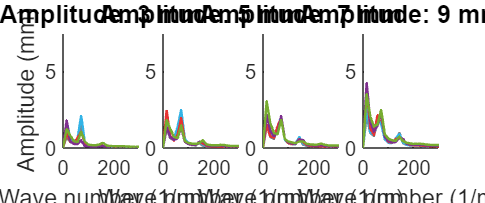

clear;
close all;
clc;

% Parameters
date = '09';
%rotation_rates_2 = [0.4189, 0.8378];
%rotation_rates_labels_2 = [0.0667, 0.1333];
rotation_rates = [0, 0.0524, 0.2094, 0.4189, 0.8378];
rotation_rates_labels = [0, 0.0083, 0.0333, 0.0667, 0.1333];
freq_value = 2.4;  % Only one frequency as per your example
freq_value_str = string(freq_value);
%amplitudes_2 = [3, 5, 7, 9];
amplitudes = [3, 5, 7, 9];

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Load the x and y coordinate arrays
x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

x_data = load(x_positions_file);
y_data = load(y_positions_file);

x_positions = x_data.x_positions_array; % Array of x positions
y_positions = y_data.y_positions_array; % Array of y positions
num_x_positions = length(x_positions);
L_y_axis = length(y_positions);

% Distance between points in meters (for wave number calculation)
distance_y = (y_positions(2) - y_positions(1)) / 100;
wave_num_y_axis = 2 * pi / distance_y;
wave_num_four_y_axis = (0:L_y_axis-1) * wave_num_y_axis / L_y_axis;

% Define colors for rotation rates
% Assign the two highest rotation rates specific colors
colors = lines(length(rotation_rates)); % Generate a colormap
color_map = [0.5, 0.5, 0.5;  % Color for 0 (or other low rotation rates)
             0.2, 0.7, 0.9;  % Color for intermediate rotation rates
             0.9, 0.2, 0.2;  % Adjust to high rotation rates
             colors(4,:);    % Specific color for 0.4189
             colors(5,:)];   % Specific color for 0.8378

% Initialize a figure for the combined plot
figure('Position', [100, 100, 1200, 500]);

% Loop through each amplitude
for ampl_idx = 1:length(amplitudes)
    ampl_value = amplitudes(ampl_idx);

    % Create a subplot for the current amplitude
    subplot(1, 4, ampl_idx);
    hold on;

    % Loop through each rotation rate
    for rot_idx = 1:length(rotation_rates)
        rot_rate = rotation_rates(rot_idx);

        % Load the surface height data for the current experiment
        rot_rate_str = string(rot_rate);
        ampl_value_str = string(ampl_value);
        surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate.mat', rot_rate_str, freq_value_str, ampl_value_str)];

        % Check if the file exists to avoid errors
        if ~isfile(surface_height_file)
            warning('File %s not found. Skipping.', surface_height_file);
            continue;
        end

        % Load data
        data = load(surface_height_file);
        surface_height_3D = data.surface_height_3D; % 3D matrix (x, y, time)

        % Preallocate for accumulating Fourier transforms
        accumulated_fourier = zeros(1, L_y_axis);

        % Loop through each x-position
        for i = 1:num_x_positions
            % Select surface height data at current x position and specific timestamp (e.g., timestamp 80)
            surf_height_y_axis = surface_height_3D(i, :, 80);

            % Fit a polynomial (e.g., a linear fit) to the surface height data
            p_y_axis = polyfit(y_positions, surf_height_y_axis, 1);  % 1 for linear fit

            % Calculate the fitted values and get fluctuations
            fitted_values_y_axis = polyval(p_y_axis, y_positions);
            fluctuations_y_axis = surf_height_y_axis - fitted_values_y_axis;

            % Fourier transform over y-axis fluctuations
            four_1d_y_axis = fft(fluctuations_y_axis / 100);

            % Accumulate the Fourier transform
            accumulated_fourier = accumulated_fourier + abs(four_1d_y_axis / L_y_axis);
        end

        % Average the accumulated Fourier transform
        average_fourier = accumulated_fourier / num_x_positions;

        % Restrict to wave numbers in the range 0 to 500
        within_range = wave_num_four_y_axis <= 500;
        wave_num_filtered = wave_num_four_y_axis(within_range);
        fourier_filtered = 2 * average_fourier(within_range);

        % Plot the average Fourier transform for the current rotation rate
        % plot(wave_num_filtered, fourier_filtered * 1000, 'LineWidth', 1.5, ...
        %      'DisplayName', sprintf('Rot Rate: %.4f Hz', rotation_rates_labels(rot_idx)));
        plot(wave_num_filtered, fourier_filtered * 1000, 'LineWidth', 1.5, ...
             'Color', color_map(rot_idx, :), ...
             'DisplayName', sprintf('Rot Rate: %.4f Hz', rotation_rates_labels(rot_idx)));
    end

    % Formatting for the subplot
    xlim([0 300]);
    ylim([0 7.5]);
    ax = gca;
    ax.FontSize = 12;
    pbaspect([1 1.5 1]);
    if ampl_idx == 1
        ylabel('Amplitude (mm)', 'FontSize', 14);
    end
    xlabel('Wave number (1/m)', 'FontSize', 14);
    title(sprintf('Amplitude: %d mm', ampl_value), 'FontSize', 15);

    % % Add a legend to the last subplot
    % if ampl_idx == length(amplitudes)
    %     legend('show', 'Location', 'eastoutside', 'FontSize', 10);
    % end
    % % Add the legend to the first subplot in the middle
    % if ampl_idx == 1
    %     legend('show', 'Location', 'northwest', 'FontSize', 10, 'Box', 'on');
    %     legend('Position', [0.2, 0.55, 0.1, 0.1]); % Adjust legend position to be inside
    % end
end

% % Add an overarching title for the figure
% sgtitle('Average FFT for Different Rotation Rates and Amplitudes', 'FontSize', 18, 'FontWeight', 'bold');

% Save the combined figure in different formats
figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\FFT\';
saveas(gcf, [figures_directory, sprintf('Combined_FFT_All_Rotations_%sHz.png', freq_value_str)]); % Save as PNG
print(gcf, [figures_directory, sprintf('Combined_FFT_All_Rotations_%sHz.eps', freq_value_str)], '-depsc'); % Save as EPS

clear;
close all;
clc;

% Parameters
date = '09';
rotation_rates = [0, 0.0524, 0.2094, 0.4189, 0.8378];
rotation_rates_labels = [0, 0.0083, 0.0333, 0.0667, 0.1333];
freq_values = [2.5, 2.6, 2.7, 2.8];  % Frequencies for the subplots
amplitude = 9;  % Fixed amplitude for all plots

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Load the x and y coordinate arrays
x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

x_data = load(x_positions_file);
y_data = load(y_positions_file);

x_positions = x_data.x_positions_array; % Array of x positions
y_positions = y_data.y_positions_array; % Array of y positions
num_x_positions = length(x_positions);
L_y_axis = length(y_positions);

% Distance between points in meters (for wave number calculation)
distance_y = (y_positions(2) - y_positions(1)) / 100;
wave_num_y_axis = 2 * pi / distance_y;
wave_num_four_y_axis = (0:L_y_axis-1) * wave_num_y_axis / L_y_axis;

% Define colors for rotation rates
colors = lines(length(rotation_rates)); % Generate a colormap

% Initialize a figure for the combined plot
figure('Position', [100, 100, 1200, 500]);

% Loop through each frequency for the subplots
for freq_idx = 1:length(freq_values)
    freq_value = freq_values(freq_idx);
    freq_value_str = string(freq_value);

    % Create a subplot for the current frequency
    subplot(1, 4, freq_idx);
    hold on;

    % Loop through available rotation rates
    for rot_idx = 1:length(rotation_rates)
        rot_rate = rotation_rates(rot_idx);

        % Load the surface height data for the current experiment
        rot_rate_str = string(rot_rate);
        ampl_value_str = string(amplitude);
        surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate.mat', rot_rate_str, freq_value_str, ampl_value_str)];

        % Check if the file exists to avoid errors
        if ~isfile(surface_height_file)
            warning('File %s not found. Skipping.', surface_height_file);
            continue;
        end

        % Load data
        data = load(surface_height_file);
        surface_height_3D = data.surface_height_3D; % 3D matrix (x, y, time)

        % Preallocate for accumulating Fourier transforms
        accumulated_fourier = zeros(1, L_y_axis);

        % Loop through each x-position
        for i = 1:num_x_positions
            % Select surface height data at current x position and specific timestamp (e.g., timestamp 80)
            surf_height_y_axis = surface_height_3D(i, :, 80);

            % Fit a polynomial (e.g., a linear fit) to the surface height data
            p_y_axis = polyfit(y_positions, surf_height_y_axis, 1);  % 1 for linear fit

            % Calculate the fitted values and get fluctuations
            fitted_values_y_axis = polyval(p_y_axis, y_positions);
            fluctuations_y_axis = surf_height_y_axis - fitted_values_y_axis;

            % Fourier transform over y-axis fluctuations
            four_1d_y_axis = fft(fluctuations_y_axis / 100);

            % Accumulate the Fourier transform
            accumulated_fourier = accumulated_fourier + abs(four_1d_y_axis / L_y_axis);
        end

        % Average the accumulated Fourier transform
        average_fourier = accumulated_fourier / num_x_positions;

        % Restrict to wave numbers in the range 0 to 500
        within_range = wave_num_four_y_axis <= 500;
        wave_num_filtered = wave_num_four_y_axis(within_range);
        fourier_filtered = 2 * average_fourier(within_range);

        % Plot the average Fourier transform for the current rotation rate
        plot(wave_num_filtered, fourier_filtered * 1000, 'LineWidth', 1.5, ...
             'Color', colors(rot_idx, :), ...
             'DisplayName', sprintf('Rot Rate: %.4f Hz', rotation_rates_labels(rot_idx)));
    end

    % Formatting for the subplot
    xlim([0 300]);
    ylim([0 9]);
    ax = gca;
    ax.FontSize = 12;
    pbaspect([1 1.5 1]);
    if freq_idx == 1
        ylabel('Amplitude (mm)', 'FontSize', 14);
    end
    xlabel('Wave number (1/m)', 'FontSize', 14);
    title(sprintf('Frequency: %.1f Hz', freq_value), 'FontSize', 15);

    % Add a legend to the first subplot
    if freq_idx == 1
        legend('show', 'Location', 'northwest', 'FontSize', 10, 'Box', 'on');
    end
end

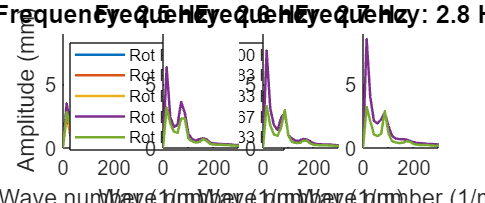


% Save the combined figure in different formats
figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\FFT\';
saveas(gcf, [figures_directory, 'Combined_FFT_Amplitude9_Frequencies.png']); % Save as PNG
print(gcf, [figures_directory, 'Combined_FFT_Amplitude9_Frequencies.eps'], '-depsc'); % Save as EPS

clear; 
close all;
clc;

% Define the rotation rate and constants for the experiment
rot_rate = 0.2094;  % Single rotation rate (in rad/s)
freq_value = 2.5;   % Constant frequency value
ampl_value = 9;     % Constant amplitude value

% Convert to string format for file names
freq_value = string(freq_value);
ampl_value = string(ampl_value);
rot_rate = string(rot_rate);

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Load the x and y coordinate arrays
x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

x_data = load(x_positions_file);
y_data = load(y_positions_file);

x_positions = x_data.x_positions_array; % Array of x positions
y_positions = y_data.y_positions_array; % Array of y positions

t_index = 131; % Time index for the data slice

% Load the surface height data for the selected rotation rate
surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate.mat', rot_rate, freq_value, ampl_value)];
data = load(surface_height_file);
surface_height_3D = data.surface_height_3D; % 3D matrix (x, y, time)

% Prepare figure for the waterfall or contour plot
figure;
hold on;

% Preallocate matrices for contour plot
fft_matrix = zeros(length(x_positions), length(y_positions)); % Store FFT magnitude

% Loop over each x-position
for x_index = 1:length(x_positions)
    % Extract the surface height data for a specific x-position and time slice
    surf_height_y_axis = surface_height_3D(x_index,:,t_index);
    
    % Fit a polynomial (linear fit) to subtract the mean trend
    p_y_axis = polyfit(y_positions, surf_height_y_axis, 1);
    fitted_values_y_axis = polyval(p_y_axis, y_positions);
    
    % Obtain fluctuations by subtracting the fitted trend
    fluctuations_y_axis = surf_height_y_axis - fitted_values_y_axis;
    
    % Compute the Fourier transform of the fluctuations
    four_1d_y_axis = fft(fluctuations_y_axis / 100); % Convert to meters
    
    % Distance between points in meters
    distance_y = (y_positions(2) - y_positions(1)) / 100;
    L_y_axis = length(fluctuations_y_axis / 100);
    
    % Wave number (spatial frequency)
    wave_num_y_axis = 2 * pi / distance_y;
    wave_num_four_y_axis = (0:length(four_1d_y_axis)-1) * wave_num_y_axis / length(four_1d_y_axis);
    
    % Scale and normalize the Fourier transform
    fft_magnitude = 2 * abs(four_1d_y_axis / L_y_axis)*100;
    
    % Store FFT magnitude for contour plot
    fft_matrix(x_index, :) = fft_magnitude;
end


%% Contour plot option
figure;

% Create a contour plot of the FFT magnitude over x-positions
contourf(wave_num_four_y_axis, x_positions, fft_matrix, 'LineColor', 'none');
colorbar;
c = colorbar; % Create colorbar
c.Label.String = 'Amplitude (cm)'; % Label for the colorbar
xlabel('Wave number (1/m)');
ylabel('X position (m)');
title(['Contour plot of FFT for ' rot_rate ' rad/s']);
xlim([0 200]); % Adjust based on your wave number range

% Save the contour plot as PNG and MATLAB figure
contour_file_name = [figures_directory, sprintf('contour_plot_fft_xpos_%sHz_%smm_%sradps', freq_value, ampl_value, rot_rate)];

Save as MATLAB figure and PNG
savefig([contour_file_name, '.fig']);
saveas(gcf, [contour_file_name, '.png']);


% Contour plots, four together

clear; 
close all;
clc;

%rot_rates = [0, 0.0524, 0.1047, 0.2094, 0.4189, 0.8378]; % Example rotation rates in rad/s
rot_rates = [0, 0.0524, 0.2094, 0.4189, 0.8378]; % Example rotation rates in rad/s

amplitudes = [3, 5, 7, 9]; % Example amplitudes in mm
freq_value = 2.5; % Constant frequency value
freq_value = string(freq_value);
%rotation_rates_labels = [0, 0.0083, 0.0167, 0.0333, 0.0667, 0.1333];
rotation_rates_labels = [0, 0.0083, 0.0333, 0.0667, 0.1333];

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Load the x and y coordinate arrays
x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

x_data = load(x_positions_file);
y_data = load(y_positions_file);

x_positions = x_data.x_positions_array; % Array of x positions
y_positions = y_data.y_positions_array; % Array of y positions

t_index = 80; % Time index for the data slice

% Loop over each rotation rate
for rot_index = 1:length(rot_rates)
    rot_rate = rot_rates(rot_index); % Current rotation rate
    rot_rate_str = string(rot_rate); % Convert to string format for file names
    rot_rate_label = rotation_rates_labels(rot_index);

    
    % Create a new figure for the current rotation rate
    figure;
    figure('Position', [100, 50, 1200, 400]); % Adjust figure size for better visibility
    
    % Create an invisible uicontrol for extra padding above the sgtitle
    uicontrol('Style', 'text', 'Position', [0, 460, 1200, 40], 'Visible', 'off');

    % Define array to store subplot axes
    subplot_axes = gobjects(1, length(amplitudes)); % Preallocate array for axes handles

    % Loop over each amplitude
    for amp_index = 1:length(amplitudes)
        ampl_value = amplitudes(amp_index); % Current amplitude
        ampl_value_str = string(ampl_value); % Convert to string format for file names
        
        % Load the surface height data for the selected rotation rate and amplitude
        surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate.mat', rot_rate_str, freq_value, ampl_value_str)];
        data = load(surface_height_file);
        surface_height_3D = data.surface_height_3D; % 3D matrix (x, y, time)

        % Preallocate matrix for contour plot
        fft_matrix = zeros(length(x_positions), length(y_positions)); % Store FFT magnitude

        % Loop over each x-position
        for x_index = 1:length(x_positions)
            % Extract the surface height data for a specific x-position and time slice
            surf_height_y_axis = surface_height_3D(x_index, :, t_index);

            % Fit a polynomial (linear fit) to subtract the mean trend
            p_y_axis = polyfit(y_positions, surf_height_y_axis, 1);
            fitted_values_y_axis = polyval(p_y_axis, y_positions);

            % Obtain fluctuations by subtracting the fitted trend
            fluctuations_y_axis = surf_height_y_axis - fitted_values_y_axis;

            % Compute the Fourier transform of the fluctuations
            four_1d_y_axis = fft(fluctuations_y_axis / 100); % Convert to meters

            % Distance between points in meters
            distance_y = (y_positions(2) - y_positions(1)) / 100;
            L_y_axis = length(fluctuations_y_axis / 100);

            % Wave number (spatial frequency)
            wave_num_y_axis = 2 * pi / distance_y;
            wave_num_four_y_axis = (0:length(four_1d_y_axis)-1) * wave_num_y_axis / length(four_1d_y_axis);

            % Scale and normalize the Fourier transform
            fft_magnitude = 2 * abs(four_1d_y_axis / L_y_axis) * 100;

            % Store FFT magnitude for contour plot
            fft_matrix(x_index, :) = fft_magnitude;
        end

        % Create a subplot for the contour plot of the FFT magnitude over x-positions
        % subplot(1, 4, amp_index); % Create 1 row and 4 columns of subplots
        % contourf(wave_num_four_y_axis, x_positions, fft_matrix, 'LineColor', 'none');
        subplot_axes(amp_index) = subplot(1, 4, amp_index);
        contourf(wave_num_four_y_axis, x_positions, fft_matrix, 'LineColor', 'none');
        ax = subplot_axes(amp_index);
        set(ax, 'XLim', [0 200]); % Apply xlim via handle

        %xlim([0 200]);
        %ax = gca;
        ax.FontSize = 15;
        pbaspect([1 1.5 1]);

        % Set y-label only for the first subplot
        if amp_index == 1
            ylabel('X position (m)');
        end

        % Set title for amplitude if rotation rate is 0
        if rot_rate == 0 || rot_rate == 0.4189
            title(sprintf('Amplitude: %d mm', ampl_value), 'FontSize', 15);
        end

        
    %sgtitle(sprintf('Rotation Rate: %.4f Hz', rot_rate_label), 'FontSize', 15, 'FontWeight', 'bold');
    
    annotation('textbox', [0.4, 0.85, 0.3, 0.05], 'String', sprintf('Rotation Rate: %.4f Hz', rot_rate_label), ...
           'HorizontalAlignment', 'center', 'FontSize', 15, 'FontWeight', 'bold', 'EdgeColor', 'none');

    end
    
    for i = 1:length(subplot_axes)
        set(subplot_axes(i), 'XLim', [0 200]);
    end

    % % Add the x-label below the last row of subplots
    % xlabel('Wave number (1/m)', 'FontSize', 15, 'Position', [0.2, -0.6, 0]); % Centered position below the subplots
    % % Adjust position of the axes to remove extra whitespace
    % for i = 1:length(subplot_axes) % Assuming you stored subplot handles in `subplot_axes`
    %     ax = subplot_axes(i);
    %     pos = get(ax, 'Position');
    %     tightInset = get(ax, 'TightInset');
    %     % Adjust position to remove left whitespace and accommodate colorbar
    %     set(ax, 'Position', [pos(1) - tightInset(1), pos(2), pos(3) + tightInset(1), pos(4)]);
    % end
    % Increase the figure's outer position to avoid cutting off the label
    set(gcf, 'OuterPosition', [100, 50, 1200, 600]);
    
    annotation('textbox', [0.4, 0.13, 0.3, 0.05], 'String', 'Wave number (1/m)', ...
           'HorizontalAlignment', 'center', 'FontSize', 15, 'EdgeColor', 'none');


    % Create colorbar only for the last subplot
    %c = colorbar('Position', [0.92, 0.11, 0.02, 0.815]); % Position it on the right
    c = colorbar('Position', [0.92, 0.11, 0.02, 0.7]); % Position it on the right
    clim([0, 1]);
    c.Label.String = 'Amplitude (cm)'; % Label for the colorbar

    % Adjust axis and insets to remove excess whitespace
    %set(gca, 'LooseInset', get(gca, 'TightInset')); % Remove outer padding around axis
    %axis tight; % Fit the axis tightly around data
    % Save the figure in different formats
    figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\';
    saveas(gcf, [figures_directory, sprintf('contour_plots_RotationRate_%.4fradps_%sHz.png', rot_rate_str, freq_value)]); % Save the figure as .png file
    print(gcf, [figures_directory, sprintf('contour_plots_RotationRate_%.4fradps_%sHz.eps', rot_rate_str, freq_value)], '-depsc'); % Save as .eps
    
    % Close the figure to save memory
    close(gcf);
end

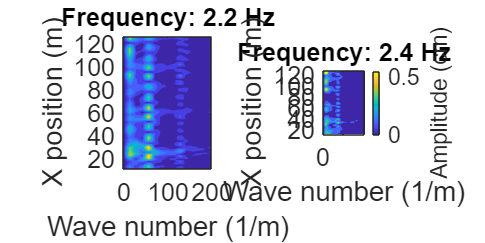

clear;
close all;
clc;

% Parameters for the analysis
rot_rate = 0.8378; % Fixed rotation rate in rad/s
amplitude = 7; % Fixed amplitude in mm
freq_values = [2.2, 2.4]; % Frequency values to compare
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\'; % File path for data

% Load the x and y coordinate arrays
x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

x_data = load(x_positions_file);
y_data = load(y_positions_file);

x_positions = x_data.x_positions_array; % Array of x positions
y_positions = y_data.y_positions_array; % Array of y positions

t_index = 80; % Time index for the data slice

% Create a new figure
figure;
set(gcf, 'Position', [100, 50, 1200, 600]); % Adjust figure size

% Loop over each frequency value
for freq_index = 1:length(freq_values)
    freq_value = freq_values(freq_index); % Current frequency value
    freq_value_str = string(freq_value); % Convert to string format for file names

    % Load the surface height data
    surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate.mat', ...
        string(rot_rate), freq_value_str, string(amplitude))];
    data = load(surface_height_file);
    surface_height_3D = data.surface_height_3D; % 3D matrix (x, y, time)

    % Preallocate matrix for contour plot
    fft_matrix = zeros(length(x_positions), length(y_positions)); % Store FFT magnitude

    % Loop over each x-position
    for x_index = 1:length(x_positions)
        % Extract the surface height data for a specific x-position and time slice
        surf_height_y_axis = surface_height_3D(x_index, :, t_index);

        % Fit a polynomial (linear fit) to subtract the mean trend
        p_y_axis = polyfit(y_positions, surf_height_y_axis, 1);
        fitted_values_y_axis = polyval(p_y_axis, y_positions);

        % Obtain fluctuations by subtracting the fitted trend
        fluctuations_y_axis = surf_height_y_axis - fitted_values_y_axis;

        % Compute the Fourier transform of the fluctuations
        four_1d_y_axis = fft(fluctuations_y_axis / 100); % Convert to meters

        % Distance between points in meters
        distance_y = (y_positions(2) - y_positions(1)) / 100;
        L_y_axis = length(fluctuations_y_axis / 100);

        % Wave number (spatial frequency)
        wave_num_y_axis = 2 * pi / distance_y;
        wave_num_four_y_axis = (0:length(four_1d_y_axis)-1) * wave_num_y_axis / length(four_1d_y_axis);

        % Scale and normalize the Fourier transform
        fft_magnitude = 2 * abs(four_1d_y_axis / L_y_axis) * 100;

        % Store FFT magnitude for contour plot
        fft_matrix(x_index, :) = fft_magnitude;
    end

    % Create a subplot for the current frequency value
    subplot(1, 2, freq_index);
    contourf(wave_num_four_y_axis, x_positions, fft_matrix, 'LineColor', 'none');
    set(gca, 'XLim', [0 200], 'FontSize', 15);
    pbaspect([1 1.5 1]);
    ylabel('X position (m)');
    xlabel('Wave number (1/m)');
    title(sprintf('Frequency: %.1f Hz', freq_value), 'FontSize', 15);
    
    % Set consistent color range for the colorbar
    caxis([0 0.55]);
    % Add the colorbar only for the right subplot
    if freq_index == 2
        c = colorbar;
        c.Label.String = 'Amplitude (cm)'; % Label for the colorbar
    end
end

% Add an overall title
%sgtitle(sprintf('Rotation Rate: %.4f rad/s', rot_rate), 'FontSize', 18, 'FontWeight', 'bold');

% Save the figure
figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\FFT\Contour plots\New\';
saveas(gcf, [figures_directory, sprintf('subplots_RotRate_%.4fradps_Amp_%dmm.png', rot_rate, amplitude)]);
print(gcf, [figures_directory, sprintf('subplots_RotRate_%.4fradps_Amp_%dmm.eps', rot_rate, amplitude)], '-depsc');

clear  
close all
clc

% Parameters
date = '09';
rotation_rates = [0, 0.0524, 0.1047, 0.2094, 0.4189, 0.8378];
frequencies = 2.4;  % Only one frequency as per your example
amplitudes = [3, 5, 7, 9];

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Load the x and y coordinate arrays
x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

x_data = load(x_positions_file);
y_data = load(y_positions_file);

x_positions = x_data.x_positions_array; % Array of x positions
y_positions = y_data.y_positions_array; % Array of y positions
num_x_positions = length(x_positions);
L_y_axis = length(y_positions);

% Distance between points in meters (for wave number calculation)
distance_y = (y_positions(2) - y_positions(1)) / 100;
wave_num_y_axis = 2 * pi / distance_y;
wave_num_four_y_axis = (0:L_y_axis-1) * wave_num_y_axis / L_y_axis;

% Initialize a table to store results
results_table = table('Size', [0 8], ...
                      'VariableTypes', {'double', 'double', 'double', 'double', 'double', 'double', 'double', 'double'}, ...
                      'VariableNames', {'RotationRate', 'Amplitude', 'Peak1_WaveNumber', 'Peak1_Amplitude_mm', ...
                                       'Peak2_WaveNumber', 'Peak2_Amplitude_mm', 'Peak3_WaveNumber', 'Peak3_Amplitude_mm'});

% Loop through each rotation rate and amplitude combination
for rot_rate = rotation_rates
    for ampl_value = amplitudes
        % Load the surface height data for the current experiment
        rot_rate_str = string(rot_rate);
        ampl_value_str = string(ampl_value);
        surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate.mat', rot_rate_str, string(frequencies), ampl_value_str)];
        
        % Check if the file exists to avoid errors
        if ~isfile(surface_height_file)
            warning('File %s not found. Skipping.', surface_height_file);
            continue
        end
        
        % Load data
        data = load(surface_height_file);
        surface_height_3D = data.surface_height_3D; % 3D matrix (x, y, time)

        % Preallocate for accumulating Fourier transforms
        accumulated_fourier = zeros(1, L_y_axis);

        % Loop through each x-position
        for i = 1:num_x_positions
            % Select surface height data at current x position and specific timestamp (e.g., timestamp 131)
            surf_height_y_axis = surface_height_3D(i, :, 80);

            % Fit a polynomial (e.g., a linear fit) to the surface height data
            p_y_axis = polyfit(y_positions, surf_height_y_axis, 1);  % 1 for linear fit

            % Calculate the fitted values and get fluctuations
            fitted_values_y_axis = polyval(p_y_axis, y_positions);
            fluctuations_y_axis = surf_height_y_axis - fitted_values_y_axis;

            % Fourier transform over y-axis fluctuations
            four_1d_y_axis = fft(fluctuations_y_axis / 100);

            % Accumulate the Fourier transform
            accumulated_fourier = accumulated_fourier + abs(four_1d_y_axis / L_y_axis);
        end

        % Average the accumulated Fourier transform
        average_fourier = accumulated_fourier / num_x_positions;

        % Restrict to wave numbers in the range 0 to 500
        within_range = wave_num_four_y_axis <= 500;
        wave_num_filtered = wave_num_four_y_axis(within_range);
        fourier_filtered = 2 * average_fourier(within_range);

        % Find the three highest peaks in the restricted Fourier transform
        [peaks, locs] = findpeaks(fourier_filtered, 'SortStr', 'descend');
        
        % Ensure there are at least three peaks
        num_peaks = min(3, length(peaks));
        peak_amplitudes_mm = nan(1, 3);
        peak_wave_numbers = nan(1, 3);
        
        for k = 1:num_peaks
            peak_amplitudes_mm(k) = peaks(k) * 1000; % Convert to mm
            peak_wave_numbers(k) = wave_num_filtered(locs(k));
        end

        % Sort peaks by wave number (ascending order)
        [peak_wave_numbers_sorted, sort_idx] = sort(peak_wave_numbers, 'ascend');
        peak_amplitudes_sorted_mm = peak_amplitudes_mm(sort_idx);

        % Append results to the table in sorted order
        results_table = [results_table; {rot_rate, ampl_value, peak_wave_numbers_sorted(1), peak_amplitudes_sorted_mm(1), ...
                                         peak_wave_numbers_sorted(2), peak_amplitudes_sorted_mm(2), peak_wave_numbers_sorted(3), peak_amplitudes_sorted_mm(3)}];

        % Plot the average Fourier transform
        figure;
        plot(wave_num_four_y_axis, 2 * average_fourier * 1000); % Convert amplitude to mm for plotting
        hold on;
        plot(peak_wave_numbers_sorted, peak_amplitudes_sorted_mm, 'ro', 'MarkerSize', 6, 'MarkerFaceColor', 'r'); % Mark peaks
        hold off;
        xlabel('Wave number (1/m)');
        ylabel('Amplitude (mm)');
        %title(sprintf('Average FFT over x positions, y axis %.4frad/s, %dHz, %dmm', rot_rate, frequencies, ampl_value));
        xlim([0 300]);
        ylim([0 5.1]);
        ax = gca;
        ax.FontSize = 15;
        pbaspect([1 2 1]);

        % Save the figure in different formats
        figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\';
        file_name = [figures_directory, sprintf('Average_FFT_y_axis_%sradps_%sHz_%smm', rot_rate_str, string(frequencies), ampl_value_str)];

        % Save as PNG file
        saveas(gcf, [file_name, '.png']); % Save the figure as .png file

        % Save as EPS file
        print(gcf, [file_name, '.eps'], '-depsc'); % Save the figure as .eps file

        % Close the figure to save memory
        close(gcf);
    end
end

% Save results table to a CSV file
results_table_file = [file_path, 'FFT_Peaks_WaveNumbers_Amplitudes_2.4Hz.csv'];
writetable(results_table, results_table_file);

disp('Processing complete. Results saved in FFT_Peaks_WaveNumbers_Amplitudes_mm_Sorted.csv');


clear 
close all
clc

date = '09';
rot_rate = 0.4189;
rot_rate = string(rot_rate);
freq_value = 2.4;
freq_value = string(freq_value);
ampl_value = 7;
ampl_value = string(ampl_value);

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Load the surface height data
surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate.mat', rot_rate, freq_value, ampl_value)];
data = load(surface_height_file);
surface_height_3D = data.surface_height_3D; % 3D matrix (x, y, time)

% Load the x and y coordinate arrays
x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

x_data = load(x_positions_file);
y_data = load(y_positions_file);

x_positions = x_data.x_positions_array; % Array of x positions
y_positions = y_data.y_positions_array; % Array of y positions


surf_height_y_axis = surface_height_3D(170,:,131);

% Fit a polynomial (e.g., a linear fit) to the surface height data
p_y_axis = polyfit(y_positions, surf_height_y_axis, 1);  % 1 for linear fit

% Calculate the fitted values
fitted_values_y_axis = polyval(p_y_axis, y_positions);

% Subtract the fitted values from the original data to obtain the fluctuations
fluctuations_y_axis = surf_height_y_axis - fitted_values_y_axis;

%Fourier over y axis
four_1d_y_axis = fft(fluctuations_y_axis/100);
% Distance between points in meters
distance_y = (y_positions(2) - y_positions(1)) / 100
L_y_axis = length(fluctuations_y_axis/100)


wave_num_y_axis = 2*pi/distance_y;
wave_num_four_y_axis = (0:length(four_1d_y_axis)-1)*wave_num_y_axis/length(four_1d_y_axis);

% Plot the Fourier transform against frequencies
plot(wave_num_four_y_axis,2*abs(four_1d_y_axis/L_y_axis))
xlabel('Wave number')
ylabel('Amplitude (m)')
title(sprintf('FFT y axis %s %sHz %smm',rot_rate,freq_value,string(ampl_value)))
xlim([0 500]);
% ylim([0 8]);

% Save the figure in different formats
% Directory for saving figures
figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\';
file_name = [figures_directory, sprintf('FFT_y_axis_%sradps_%sHz_%smm', rot_rate, freq_value, ampl_value)]; % Combine directory and file name


% Save as PNG file
saveas(gcf, [file_name, '.png']); % Save the figure as .png file

% Save as EPS file
print(gcf, [file_name, '.eps'], '-depsc'); % Save the figure as .eps file

clear;
close all;
clc;

% Define the rotation rates for different experiments
rot_rates = [0, 0.0524, 0.1047, 0.2094, 0.4189, 0.8378];
freq_value = 2.2;   % Constant frequency value
ampl_value = 9;     % Constant amplitude value

% Convert to string format for file names
freq_value = string(freq_value);
ampl_value = string(ampl_value);

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Load the x and y coordinate arrays
x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

x_data = load(x_positions_file);
y_data = load(y_positions_file);

x_positions = x_data.x_positions_array; % Array of x positions
y_positions = y_data.y_positions_array; % Array of y positions

x_index = 310;
t_index = 131;

% Prepare figure for the waterfall plot
figure;
hold on;

% Loop over each rotation rate
for i = 1:length(rot_rates)
    % Convert the current rotation rate to string format
    rot_rate = string(rot_rates(i));

    % Load the surface height data
    surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate.mat', rot_rate, freq_value, ampl_value)];
    data = load(surface_height_file);
    surface_height_3D = data.surface_height_3D; % 3D matrix (x, y, time)
    
    % Extract the surface height data for a specific slice
    surf_height_y_axis = surface_height_3D(x_index,:,t_index);
    
    % Fit a polynomial (linear fit) to subtract the mean trend
    p_y_axis = polyfit(y_positions, surf_height_y_axis, 1);
    fitted_values_y_axis = polyval(p_y_axis, y_positions);
    
    % Obtain fluctuations by subtracting the fitted trend
    fluctuations_y_axis = surf_height_y_axis - fitted_values_y_axis;
    
    % Compute the Fourier transform of the fluctuations
    four_1d_y_axis = fft(fluctuations_y_axis / 100); % Convert to meters
    
    % Distance between points in meters
    distance_y = (y_positions(2) - y_positions(1)) / 100;
    L_y_axis = length(fluctuations_y_axis / 100);
    
    % Wave number (spatial frequency)
    wave_num_y_axis = 2 * pi / distance_y;
    wave_num_four_y_axis = (0:length(four_1d_y_axis)-1) * wave_num_y_axis / length(four_1d_y_axis);
    
    % Scale and normalize the Fourier transform
    fft_magnitude = 2 * abs(four_1d_y_axis / L_y_axis);
    
    % Plot the Fourier transform as a line in the waterfall plot
    % Offset each line plot in the Z direction using the loop index (i)
    waterfall_z = i * ones(size(wave_num_four_y_axis));
    plot3(wave_num_four_y_axis, waterfall_z, fft_magnitude, 'LineWidth', 1.5);
end

% Customize the plot
xlabel('Wave number (1/m)');
ylabel('Rotation rate index');
zlabel('Amplitude (m)');
title('Waterfall plot of FFT over y-axis for varying rotation rates');
xlim([0 500]);
grid on;
view(3); % 3D view for waterfall plot

% Add rotation rate labels to the y-axis
yticks(1:length(rot_rates));
yticklabels(string(rot_rates) + ' rad/s');

% Save the figure in different formats
% Directory for saving figures
figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\';
file_name = [figures_directory, sprintf('waterfall_plot_fft_%sHz_%smm', freq_value, ampl_value)]; % Combine directory and file name

% % Save as a MATLAB figure (.fig)
% savefig([file_name, '.fig']); % Use savefig for .fig file
% 
% % Save as PNG file
% saveas(gcf, [file_name, '.png']); % Save the figure as .png file

clear;
close all;
clc;

% Define the rotation rate and constants for the experiment
rot_rate = 0.2094;  % Single rotation rate (in rad/s)
freq_value = 2.5;   % Constant frequency value
ampl_value = 9;     % Constant amplitude value

% Convert to string format for file names
freq_value = string(freq_value);
ampl_value = string(ampl_value);
rot_rate = string(rot_rate);

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Load the x and y coordinate arrays
x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

x_data = load(x_positions_file);
y_data = load(y_positions_file);

x_positions = x_data.x_positions_array; % Array of x positions
y_positions = y_data.y_positions_array; % Array of y positions

t_index = 131; % Time index for the data slice

% Load the surface height data for the selected rotation rate
surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate.mat', rot_rate, freq_value, ampl_value)];
data = load(surface_height_file);
surface_height_3D = data.surface_height_3D; % 3D matrix (x, y, time)

% Prepare figure for the waterfall or contour plot
figure;
hold on;

% Preallocate matrices for contour plot
fft_matrix = zeros(length(x_positions), length(y_positions)); % Store FFT magnitude

% Loop over each x-position
for x_index = 1:length(x_positions)
    % Extract the surface height data for a specific x-position and time slice
    surf_height_y_axis = surface_height_3D(x_index,:,t_index);
    
    % Fit a polynomial (linear fit) to subtract the mean trend
    p_y_axis = polyfit(y_positions, surf_height_y_axis, 1);
    fitted_values_y_axis = polyval(p_y_axis, y_positions);
    
    % Obtain fluctuations by subtracting the fitted trend
    fluctuations_y_axis = surf_height_y_axis - fitted_values_y_axis;
    
    % Compute the Fourier transform of the fluctuations
    four_1d_y_axis = fft(fluctuations_y_axis / 100); % Convert to meters
    
    % Distance between points in meters
    distance_y = (y_positions(2) - y_positions(1)) / 100;
    L_y_axis = length(fluctuations_y_axis / 100);
    
    % Wave number (spatial frequency)
    wave_num_y_axis = 2 * pi / distance_y;
    wave_num_four_y_axis = (0:length(four_1d_y_axis)-1) * wave_num_y_axis / length(four_1d_y_axis);
    
    % Scale and normalize the Fourier transform
    fft_magnitude = 2 * abs(four_1d_y_axis / L_y_axis)*100;
    
    % Store FFT magnitude for contour plot
    fft_matrix(x_index, :) = fft_magnitude;
    
    % For the waterfall plot
    waterfall_z = x_positions(x_index) * ones(size(wave_num_four_y_axis));
    plot3(wave_num_four_y_axis, waterfall_z, fft_magnitude, 'LineWidth', 1.5);
end

% Customize the waterfall plot
xlabel('Wave number (1/m)');
ylabel('X position (m)');
zlabel('Amplitude (cm)');
title('Waterfall plot of FFT over y-axis for varying x-positions');
xlim([0 500]); % Adjust based on your wave number range
grid on;
view(3); % 3D view for waterfall plot

% Add rotation rate label to the title
title(['Waterfall plot of FFT for ' rot_rate ' rad/s']);

% Save the waterfall plot as PNG and MATLAB figure
figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\FFT\';
file_name = [figures_directory, sprintf('waterfall_plot_fft_xpos_%sHz_%smm_%sradps', freq_value, ampl_value, rot_rate)];

% % Save as MATLAB figure and PNG
% savefig([file_name, '.fig']);
% saveas(gcf, [file_name, '.png']);

%% Contour plot option
figure;

% Create a contour plot of the FFT magnitude over x-positions
contourf(wave_num_four_y_axis, x_positions, fft_matrix, 'LineColor', 'none');
colorbar;
c = colorbar; % Create colorbar
c.Label.String = 'Amplitude (cm)'; % Label for the colorbar
xlabel('Wave number (1/m)');
ylabel('X position (m)');
title(['Contour plot of FFT for ' rot_rate ' rad/s']);
xlim([0 200]); % Adjust based on your wave number range

% Save the contour plot as PNG and MATLAB figure
contour_file_name = [figures_directory, sprintf('contour_plot_fft_xpos_%sHz_%smm_%sradps', freq_value, ampl_value, rot_rate)];

% Save as MATLAB figure and PNG
% savefig([contour_file_name, '.fig']);
% saveas(gcf, [contour_file_name, '.png']);

14.3373, 57.3493, 129.036

clear;
close all;
clc;

% Define the rotation rates and constants for the experiment
rot_rates = [0, 0.0524, 0.1047, 0.2094, 0.4189, 0.8378];
freq_value = 2.2;   % Constant frequency value
ampl_value = 9;     % Constant amplitude value

% Convert to string format for file names
freq_value = string(freq_value);
ampl_value = string(ampl_value);

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Load the x and y coordinate arrays
x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

x_data = load(x_positions_file);
y_data = load(y_positions_file);

x_positions = x_data.x_positions_array; % Array of x positions
y_positions = y_data.y_positions_array; % Array of y positions

t_index = 131; % Time index for the data slice

% Distance between points in meters (for Fourier transform calculation)
distance_y = (y_positions(2) - y_positions(1)) / 100;
wave_num_y_axis = 2 * pi / distance_y;

% Generate wave numbers for Fourier transform
L_y_axis = length(y_positions); % Number of points along the y-axis
wave_num_four_y_axis = (0:L_y_axis-1) * wave_num_y_axis / L_y_axis;

% Specify the wave numbers of the peaks manually
peak_wavenumbers = [14.3373, 57.3493, 129.036]; % Replace with actual wave numbers

% Choose which rotation rate to plot (you can change this value)
selected_rot_rate = 0.4189;  % Specify the rotation rate you want to plot

% Find the index of the selected rotation rate
selected_rot_index = find(rot_rates == selected_rot_rate);

% Initialize a matrix to store peak amplitudes for each rotation rate
num_peaks = 3; % We have 3 peaks (replace with your actual number of peaks)
peak_amplitudes = zeros(length(rot_rates), num_peaks, length(x_positions));

% Loop over each rotation rate
for r = 1:length(rot_rates)
    % Convert the current rotation rate to string format
    rot_rate = string(rot_rates(r));

    % Load the surface height data for the current rotation rate
    surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate.mat', rot_rate, freq_value, ampl_value)];
    data = load(surface_height_file);
    surface_height_3D = data.surface_height_3D; % 3D matrix (x, y, time)
    
    % Loop over each x-position
    for x_index = 1:length(x_positions)
        % Extract the surface height data for a specific x-position and time slice
        surf_height_y_axis = surface_height_3D(x_index,:,t_index);
        
        % Fit a polynomial (linear fit) to subtract the mean trend
        p_y_axis = polyfit(y_positions, surf_height_y_axis, 1);
        fitted_values_y_axis = polyval(p_y_axis, y_positions);
        
        % Obtain fluctuations by subtracting the fitted trend
        fluctuations_y_axis = surf_height_y_axis - fitted_values_y_axis;
        
        % Compute the Fourier transform of the fluctuations
        four_1d_y_axis = fft(fluctuations_y_axis / 100); % Convert to meters
        
        % Scale and normalize the Fourier transform
        fft_magnitude = 2 * abs(four_1d_y_axis / length(four_1d_y_axis)) * 100; % Convert to centimeters
        
        % Find indices of the closest wave numbers in the Fourier transform for each peak
        [~, peak_idx1] = min(abs(wave_num_four_y_axis - peak_wavenumbers(1)));
        [~, peak_idx2] = min(abs(wave_num_four_y_axis - peak_wavenumbers(2)));
        [~, peak_idx3] = min(abs(wave_num_four_y_axis - peak_wavenumbers(3)));
        
        % Store the peak amplitudes for the current x-position and rotation rate
        peak_amplitudes(r, 1, x_index) = fft_magnitude(peak_idx1); % Amplitude for first peak
        peak_amplitudes(r, 2, x_index) = fft_magnitude(peak_idx2); % Amplitude for second peak
        peak_amplitudes(r, 3, x_index) = fft_magnitude(peak_idx3); % Amplitude for third peak
    end
end

%% Plot the peak amplitude as a function of x-position for the selected rotation rate
figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\FFT\';

% Plot for the first peak
figure;
plot(x_positions, squeeze(peak_amplitudes(selected_rot_index, 1, :)), 'LineWidth', 1.5, 'DisplayName', sprintf('Rotation rate %.4f rad/s', selected_rot_rate));
xlabel('X position (cm)');
ylabel('Amplitude of first peak (cm)');
ylim([0 1]);
title(sprintf('Amplitude of first peak for rotation rate %.4f rad/s', selected_rot_rate));
grid on;
% saveas(gcf, [figures_directory sprintf('first_peak_rotation_%sHz_%smm_%.4fradps.png', freq_value, ampl_value, selected_rot_rate)]);

% Plot for the second peak
figure;
plot(x_positions, squeeze(peak_amplitudes(selected_rot_index, 2, :)), 'LineWidth', 1.5, 'DisplayName', sprintf('Rotation rate %.4f rad/s', selected_rot_rate));
xlabel('X position (cm)');
ylabel('Amplitude of second peak (cm)');
ylim([0 1]);
title(sprintf('Amplitude of second peak for rotation rate %.4f rad/s', selected_rot_rate));
grid on;
% saveas(gcf, [figures_directory sprintf('second_peak_rotation_%sHz_%smm_%.4fradps.png', freq_value, ampl_value, selected_rot_rate)]);

% Plot for the third peak
figure;
plot(x_positions, squeeze(peak_amplitudes(selected_rot_index, 3, :)), 'LineWidth', 1.5, 'DisplayName', sprintf('Rotation rate %.4f rad/s', selected_rot_rate));
xlabel('X position (cm)');
ylabel('Amplitude of third peak (cm)');
ylim([0 1]);
title(sprintf('Amplitude of third peak for rotation rate %.4f rad/s', selected_rot_rate));
grid on;
% saveas(gcf, [figures_directory sprintf('third_peak_rotation_%sHz_%smm_%.4fradps.png', freq_value, ampl_value, selected_rot_rate)]);


%% Fourier transform of the amplitude functions across x-positions
% Number of x positions and distance in x (assuming uniform spacing)
L_x = length(x_positions);
distance_x = (x_positions(2) - x_positions(1)) / 100; % Convert to meters if x_positions is in cm
wave_num_x_axis = 2 * pi / distance_x;
wave_num_four_x_axis = (0:L_x-1) * wave_num_x_axis / L_x;

% Initialize a matrix to store the dominant frequency of each peak's amplitude function
dominant_freqs = zeros(1, num_peaks);

% Loop over each peak to calculate the Fourier transform of the amplitude function
for peak_num = 1:num_peaks
    % Get the amplitude function for the selected rotation rate and current peak
    amplitude_function_x = squeeze(peak_amplitudes(selected_rot_index, peak_num, :));
    
    % Perform Fourier transform on the amplitude function along the x-axis
    four_1d_x = fft(amplitude_function_x);
    
    % Calculate the magnitude of the Fourier coefficients
    fft_magnitude_x = 2 * abs(four_1d_x / L_x);
    
    % Find the index of the dominant frequency (exclude the zero-frequency term)
    [~, dom_freq_idx] = max(fft_magnitude_x(3:end));
    
    % Store the dominant frequency in the wave number space
    dominant_freqs(peak_num) = wave_num_four_x_axis(dom_freq_idx + 2); % +1 to adjust for zero-frequency exclusion
    
    % Plot the Fourier spectrum for the current peak
    figure;
    plot(wave_num_four_x_axis(1:floor(L_x/2)), fft_magnitude_x(1:floor(L_x/2)), 'LineWidth', 1.5);
    xlabel('Wave number (1/m)');
    ylabel(sprintf('Amplitude of Fourier Transform (Peak %d)', peak_num));
    title(sprintf('Fourier Spectrum of Peak %d Amplitude Function across X-positions', peak_num));
    xlim([0 150])
    grid on;
    saveas(gcf, [figures_directory sprintf('Fourier_spectrum_peak_%d_rotation_%sHz_%smm_%.4fradps.png', peak_num, freq_value, ampl_value, selected_rot_rate)]);
end

% Display the dominant frequencies in the command window
disp('Dominant frequencies (in wave number) of the peak amplitude functions across X-positions:');
for peak_num = 1:num_peaks
    fprintf('Peak %d: %.4f (1/m)\n', peak_num, dominant_freqs(peak_num));
end


clear;
close all;
clc;

% Define the fixed rotation rate and varying frequencies
rot_rate = 0.4189;  % Fixed rotation rate
freq_values = [2.2, 2.3, 2.4, 2.5, 2.6, 2.7, 2.8]; % Varying frequencies
ampl_value = 7;    % Constant amplitude value

% Convert rot_rate and ampl_value to string format for file names
rot_rate = string(rot_rate);
ampl_value = string(ampl_value);

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Load the x and y coordinate arrays
x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

x_data = load(x_positions_file);
y_data = load(y_positions_file);

x_positions = x_data.x_positions_array; % Array of x positions
y_positions = y_data.y_positions_array; % Array of y positions

% Prepare figure for the waterfall plot
figure;
hold on;

chosen_x_position = 170;
chosen_x_position_string = string(chosen_x_position);

% Loop over each frequency value
for i = 1:length(freq_values)
    % Convert the current frequency to string format
    freq_value = string(freq_values(i));

    % Load the surface height data for the current frequency
    surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate.mat', rot_rate, freq_value, ampl_value)];
    data = load(surface_height_file);
    surface_height_3D = data.surface_height_3D; % 3D matrix (x, y, time)
    
    % Extract the surface height data for a specific slice
    surf_height_y_axis = surface_height_3D(chosen_x_position,:,100);
    
    % Fit a polynomial (linear fit) to subtract the mean trend
    p_y_axis = polyfit(y_positions, surf_height_y_axis, 1);
    fitted_values_y_axis = polyval(p_y_axis, y_positions);
    
    % Obtain fluctuations by subtracting the fitted trend
    fluctuations_y_axis = surf_height_y_axis - fitted_values_y_axis;
    
    % Compute the Fourier transform of the fluctuations
    four_1d_y_axis = fft(fluctuations_y_axis / 100); % Convert to meters
    
    % Distance between points in meters
    distance_y = (y_positions(2) - y_positions(1)) / 100;
    L_y_axis = length(fluctuations_y_axis / 100);
    
    % Wave number (spatial frequency)
    wave_num_y_axis = 2 * pi / distance_y;
    wave_num_four_y_axis = (0:length(four_1d_y_axis)-1) * wave_num_y_axis / length(four_1d_y_axis);
    
    % Scale and normalize the Fourier transform
    fft_magnitude = 2 * abs(four_1d_y_axis / L_y_axis);
    
    % Plot the Fourier transform as a line in the waterfall plot
    % Offset each line plot in the Z direction using the loop index (i)
    waterfall_z = i * ones(size(wave_num_four_y_axis));
    plot3(wave_num_four_y_axis, waterfall_z, fft_magnitude, 'LineWidth', 1.5);
end

% Customize the plot
xlabel('Wave number (1/m)');
ylabel('Frequency index');
zlabel('Amplitude (m)');
title('Waterfall plot of FFT over y-axis for varying frequencies');
xlim([0 500]);
grid on;
view(3); % 3D view for waterfall plot

% Add frequency labels to the y-axis
yticks(1:length(freq_values));
yticklabels(string(freq_values) + ' Hz');

% Save the figure in different formats
figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\';
file_name = [figures_directory, sprintf('waterfall_plot_fft_%sradps_%smm_x_pos_%s_varying_freq', rot_rate, ampl_value,chosen_x_position_string)];

% Save as a MATLAB figure (.fig)
savefig([file_name, '.fig']); % Use savefig to preserve the figure structure

% Save as PNG file
saveas(gcf, [file_name, '.png']); % Save the figure as .png file


% def calc_wave_heights_0_moment(data_gauges, sample_rate, f_start, f_end, n_segments=4):
%     '''
%     Calculates the wave heights based on the zeroth moment for each wave gauge.
% 
%     Parameters:
%         data_gauges: Pandas Dataframe
%                      Wavegauge data in SI units.
%                      Columns ["Time", "Gauge1", "Gauge2", ...]
%         sample_rate: int/float
%                      Sampling rate of the measurements by the wave gauges (Hz).
%         f_start: int/float
%                  Lower bound of frequency range for calculation of zeroth moment.
%         f_end: int/float
%                Upper bound of frequency range for calculation of zeroth moment.
%         n_segments: int
%                     Number of segments for the calculation of the psd.
% 
%     Returns:
%         Pandas Dataframe: Containing the Hm0 (m) for each wave gauge.
%                           Columns = ["Gauge", "Hm0", "Hrms", "Hmean"]
%     '''
% 
%     Hm0_gauges = []
%     Hrms_gauges = []
%     Hmean_gauges = []
%     for i in np.arange(len(data_gauges.columns) - 1):
%         gauge = "Gauge" + str(i + 1)
% 
%         spectrum, freq = power_spectral_density(data_gauges[gauge].values, sample_rate, n_segments)
%         delta_f = freq[1] - freq[0]
% 
%         psd_result = pd.DataFrame({"Frequency": freq, "Spectrum": spectrum})
%         psd_result = psd_result[(psd_result["Frequency"] >= f_start) & (psd_result["Frequency"] <= f_end)]
% 
%         moment0 = sum(psd_result["Spectrum"]) * delta_f
%         Hm0 = 4 * np.sqrt(moment0)
%         Hrms = np.sqrt(8 * moment0)
%         Hmean = np.sqrt(const.pi / 8) * 4 * np.sqrt(moment0)
% 
%         Hm0_gauges.append(Hm0)
%         Hrms_gauges.append(Hrms)
%         Hmean_gauges.append(Hmean)
% 
%     gauges = np.arange(len(data_gauges.columns) - 1) + 1
%     wave_heights = {'Gauge': pd.Series(gauges, dtype=int),
%                     'Hm0': pd.Series(Hm0_gauges, dtype=float),
%                     'Hrms': pd.Series(Hrms_gauges, dtype=float),
%                     'Hmean': pd.Series(Hmean_gauges, dtype=float)}
% 
%     return pd.DataFrame(wave_heights)

% %Fourier over short axis
% four_1d_short_axis = fft(fluctuations_short_axis/1000);
% % Distance between points in meters
% distance = (h.x(2) - h.x(1)) / 1000; 
% 
% L_short_axis = length(fluctuations_short_axis/1000);
% 
% % OPTION 3
% % Total physical length along the long axis in meters
% L_physical_short_axis = distance * L_short_axis; % L_physical_long_axis is the total length in meters
% 
% % Wave number calculation: k = 2*pi/L_physical_long_axis
% wave_num_step_short_axis = (2 * pi) / L_physical_short_axis; % Step in wave number space
% wave_num_four_short_axis = (0:(L_short_axis/2)) * wave_num_step_short_axis; % Only positive wave numbers
% 
% % Normalize the FFT result
% four_1d_short_axis_magnitude = abs(four_1d_short_axis(1:L_short_axis/2+1)) / L_short_axis; % Take only the first half
% 
% % PLOT FOR OPTION 2 & 3
% % Plot the Fourier transform against the wave number
% figure;
% plot(wave_num_four_short_axis, 2 * four_1d_short_axis_magnitude)
% xlim([0 150]);
% xlabel('Wave number (m^-1)')
% ylabel('Magnitude')
% title(sprintf('FFT over short axis %s rad/s %s Hz %s mm', rot_rate, freq_value, string(ampl_value)))
% 
% 

% output_file_png_fft_long = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_FFT_short_axis_%s.png',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% exportgraphics(gcf, output_file_png_fft_long);
% output_file_fig_fft_long = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_FFT_short_axis_%s.fig',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% savefig(gcf, output_file_fig_fft_long);


% % Performing a 2D Fourier transform on the surface heights 
% four_2d = fft2(surface_height(:,:)-mean(surface_height(:,:)));
% %plot(four_2d)
% imagesc(abs(fftshift(four_2d)));
% 
% xlim([70.0 100.0]);
% ylim([150 290]);